# Bài Tập: Thiết Kế và Kiểm Tra Bộ Điều Khiển PID cho Hệ Thống Bể Nước

**Mô Tả Bài Tập**

Bạn sẽ thiết kế một bộ điều khiển PID để điều khiển mực nước trong một bể nước. Hệ thống được mô phỏng bởi phương trình:


$$\frac{d}{dt}h(t)=\frac{1}{V}(Q_{in} -Q_{out} )$$


Trong đó:

- $h(t)$ là mực nước tại thời gian ( t ).

- $Q_{in}$ là lưu lượng nước vào bể.

- $Q=K_v \sqrt{h}$ là lưu lượng nước ra bể, với $K_v$ là hệ số thoát nước.

**Định Luật Torricelli**

$v=\sqrt{2gh}$�

trong đó:

- ( v ) là vận tốc dòng chảy (m/s),

- ( g ) là gia tốc trọng trường (9.81 m/s²),

- ( h ) là chiều cao mực nước trên lỗ hở (m).

**Mối Quan Hệ Giữa Lưu Lượng và Vận Tốc**

Lưu lượng nước qua một lỗ hở là tích của vận tốc dòng chảy và diện tích của lỗ hở:


$$Q=A\cdot v$$


trong đó:

- ( Q ) là lưu lượng nước (m³/s),

- ( A ) là diện tích lỗ hở (m²),

- ( v ) là vận tốc dòng chảy (m/s).

**Khi Thay Vận Tốc ( v ) Bằng Biểu Thức Của Định Luật Torricelli**

$Q=A\cdot \sqrt{2gh}$�

Nếu ( A ) và ( g ) được kết hợp vào một hệ số $K_v$ để đơn giản hóa, ta có:

$Q=K_v \sqrt{h}$�

**Đơn Vị của **$K_v$

Hệ số ( K_v ) là một hằng số phụ thuộc vào diện tích lỗ hở và gia tốc trọng trường. Đơn vị của ( K_v ) là lít/sqrt(cm) hoặc m³/sqrt(m), tùy thuộc vào hệ đơn vị sử dụng.

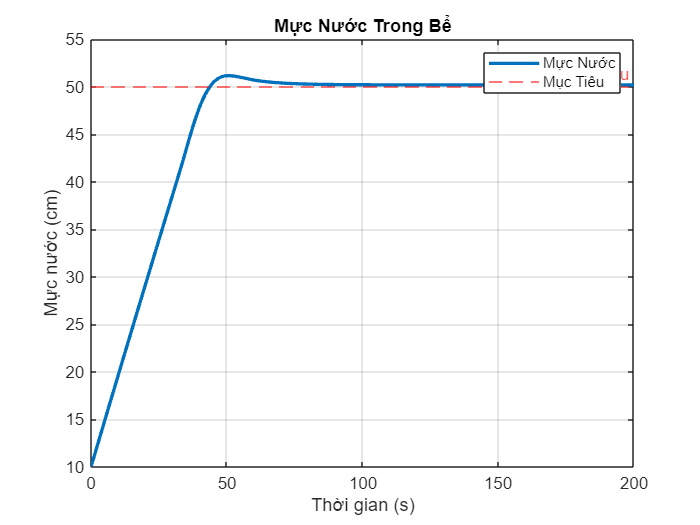

% Thiết Lập Các Tham Số Hệ Thống
clc;clearvars;
% Các thông số hệ thống
V = 10;          % Thể tích bể (m^3)
K_v = 0.1;       % Hệ số thoát nước (m^3/s/sqrt(m))
Q_in = 0.05;     % Lưu lượng nước vào (m^3/s)
Q_max = 10;      % Công suất bơm tối đa (m^3/s)
delay = 0.3;      % Hệ số trễ
inertia = 20;   % Hệ số quán tính

% Tham số PID
Kp = 1;            % Hệ số tỉ lệ
Ki = 0.001;            % Hệ số tích phân
Kd = 0.00;          % Hệ số vi phân

% Mục tiêu mực nước
h_target = 50;     % Mục tiêu mực nước (cm)

% Thời gian mô phỏng
t_max = 200;       % Thời gian mô phỏng (s)
dt = 1;          % Bước thời gian (s)
t = 0:dt:t_max;    % Mảng thời gian

% Mực nước ban đầu
h = zeros(size(t));
h(1) = 10;         % Mực nước ban đầu (cm)

% Biến lưu trữ giá trị tích phân và sai số trước đó
integral_error = 0;
prev_error = 0;

% Mô Phỏng Hệ Thống
for i = 2:length(t)
    
    % Tính giá trị điều khiển PID
    [u, integral_error, prev_error] = pid_control(h(i-1), h_target, Kp, Ki, Kd, integral_error, prev_error, dt);
    % Cập nhật mực nước
    % h(i) = tank_model(h(i-1), Q_in, K_v, V, u, dt);
    h(i) = tank_model_delay(h(i-1), Q_in, K_v, V, u, dt, Q_max, delay, inertia);
end

% Vẽ Kết Quả Mô Phỏng
figure;
plot(t, h, 'LineWidth', 2);
hold on;
yline(h_target, '--r', 'Mục Tiêu');
xlabel('Thời gian (s)');
ylabel('Mực nước (cm)');
title('Mực Nước Trong Bể');
legend('Mực Nước', 'Mục Tiêu');
grid on;


% Đánh Giá Hiệu Quả Bộ Điều Khiển PID
error = h_target - h;
mse = mean(error.^2);
disp(['MSE: ', num2str(mse)]);

MSE: 115.0467


# PID Function

**Công Thức Tính Đầu Ra PID**

$u(t)=K_p \cdot e(t)+K_i \cdot \int e(t)\;dt+K_d \cdot \frac{de(t)}{dt}$�

**Phương Trình Vi Phân của Hệ Thống**

**Trường hợp điều chỉnh lưu lượng nước vào:**

$\frac{dh(t)}{dt}=\frac{(Q_{in} +u)-Q_{out} }{V}$��

**Trường hợp điều chỉnh lưu lượng nước ra:**

$\frac{dh(t)}{dt}=\frac{Q_{in} -(Q_{out} +u)}{V}$�

**Trường hợp điều khiển kết hợp:**

$\frac{dh(t)}{dt}=\frac{(Q_{in} +u_{in} )-(Q_{out} +u_{out} )}{V}$�

**Công Thức Rời Rạc**

**Trường hợp điều chỉnh lưu lượng nước vào:**


$$h_{next} =h_{current} +\Delta t\left(\frac{Q_{in} +u-K_v \sqrt{h_{current} }}{V}\right)$$


function [u, integral_error, prev_error] = pid_control(h_current, h_target, Kp, Ki, Kd, integral_error, prev_error, dt)
    % Tính sai số
    error = h_target - h_current;
    
    % Tích phân sai số
    integral_error = integral_error + error * dt;
    
    % Đạo hàm của sai số
    derivative_error = (error - prev_error) / dt;
    
    % Tính giá trị điều khiển PID
    u = Kp * error + Ki * integral_error + Kd * derivative_error;
    
    % Cập nhật sai số trước đó
    prev_error = error;
end

# Model Function

**Mô Hình Bể Nước**

**Phương trình vi phân của mực nước:**

$\frac{dh(t)}{dt}=\frac{Q_{in} -Q_{out} }{V}$��

**Lưu lượng nước ra:**

$Q_{out} =K_v \sqrt{h(t)}$�

function h_next = tank_model(h_current, Q_in, K_v, V, u, dt)
    % Lưu lượng nước ra
    Q_out = K_v * sqrt(h_current);
    
    % Cập nhật mực nước
    h_next = h_current + dt * ((Q_in - Q_out) / V + u);
end
% Mô hình mở rộng
function h_next = tank_model_delay(h_current, Q_in, K_v, V, u, dt, Q_max, delay, inertia)
    % Bão hòa lưu lượng dòng chảy đến công suất bơm tối đa
    Q_in = Q_in + u;
    Q_in = min(max(Q_in, 0), Q_max);
    
    % Áp dụng độ trễ và quán tính cho dòng chảy vào
    persistent Q_in_delayed;
    if isempty(Q_in_delayed)
        Q_in_delayed = Q_in; 
    end
    Q_in_delayed = (1 - delay) * Q_in_delayed + delay * Q_in;
    
    % Áp dụng quán tính vào hệ số dòng chảy ra
    K_v_effective = K_v * (1 - inertia * abs(Q_in - Q_in_delayed) / Q_max);
    
    % Tính toán lưu lượng chảy ra
    Q_out = K_v_effective * sqrt(h_current);
    
    % Cập nhật mực nước với lưu lượng chảy vào và chảy ra hiệu quả
    h_next = h_current + dt * (Q_in_delayed - Q_out) / V;
end
